function [X, omega] = mrw_fft(N, lambda)
% MRW_FFT  Fast Multifractal Random Walk generator (Bacry–Delour–Muzy)
%
%   N       - length of the signal
%   lambda  - intermittency parameter (typical: 0.05–0.2)

    % Frequency grid
    k = [0:N/2, -N/2+1:-1]';
    k_abs = abs(k);
    k_abs(1) = 1;  % avoid division by zero

    % Power spectrum of log‑correlated field: S(k) ~ 1/|k|
    Sk = 1 ./ k_abs;

    % Random phases
    xi = randn(N,1) + 1i*randn(N,1);

    % Fourier domain field
    Wk = sqrt(Sk) .* xi;

    % Inverse FFT → log‑correlated Gaussian field
    omega = real(ifft(Wk));

    % Normalize variance to lambda^2
    omega = lambda * omega / std(omega);

    % Center
    omega = omega - mean(omega);

    % MRW increments
    eps = randn(N,1);
    dX = eps .* exp(omega);

    % Integrate
    X = cumsum(dX);
end


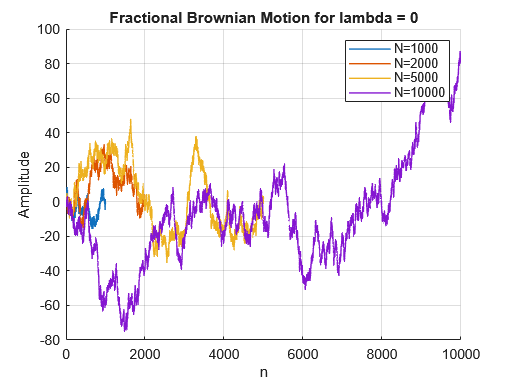

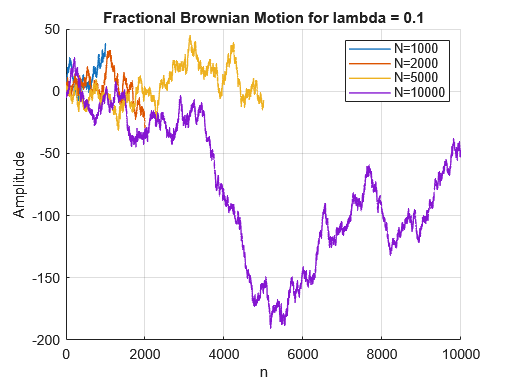

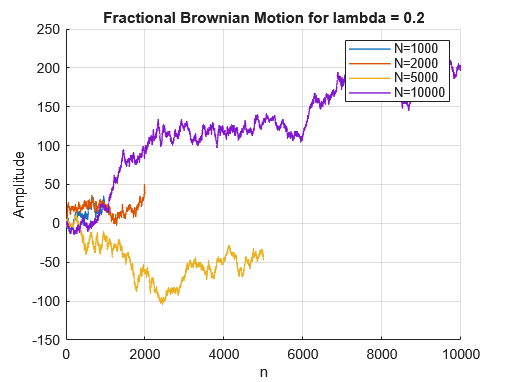

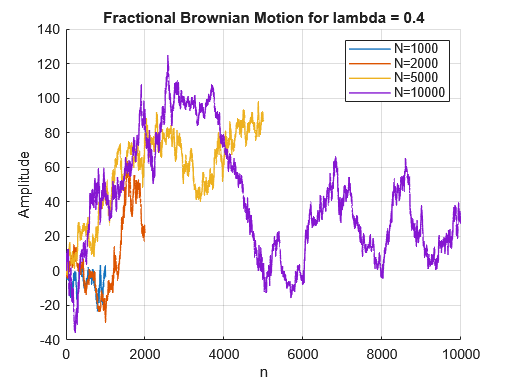

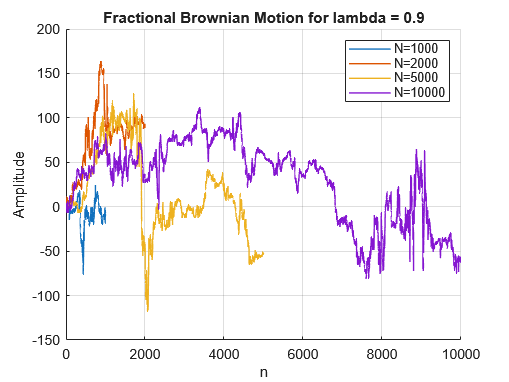

clear; close all; clc;

%% ---------------------------------------------------------
% PARAMETERS
% ---------------------------------------------------------
lambda  = [0.0, 0.1, 0.2,0.4, 0.9];                 % lambda
Nvals  = [1000, 2000, 5000,10000];       % different noise lengths
qvals  = -2:0.1:2;                            % q for tau(q)
numH   = numel(lambda);
numN   = numel(Nvals);

colorsN = lines(numN);                    % colors for different N

%% ---------------------------------------------------------
% STORAGE FOR RESULTS
% mrw{hi,ni}        - signal
% dh{hi,ni}, h{hi,ni} - multifractal spectrum
% cp{hi,ni}         - cumulants [C1 C2 C3]
% tauq{hi,ni}       - scaling function tau(q)
% leaders{hi,ni}    - leaders by scale
% structfunc{hi,ni} - structure function info (Tq, weights, logscales)
% ---------------------------------------------------------
mrw        = cell(numH, numN);
dh         = cell(numH, numN);
h          = cell(numH, numN);
cp         = cell(numH, numN);
tauq       = cell(numH, numN);
leaders    = cell(numH, numN);
structfunc = cell(numH, numN);
alpha_q    = cell(numH, numN);
f_alpha    = cell(numH, numN);
%% ---------------------------------------------------------
% MAIN LOOP: GENERATE SIGNALS AND RUN DWTLEADER ONCE
% ---------------------------------------------------------
for hi = 1:numH
    l = lambda(hi);
    for ni = 1:numN
        N = Nvals(ni);

        % Generate mrw
        [mrw{hi,ni},omega] = mrw_fft(N,l);

        % Wavelet leader multifractal analysis
        [h{hi,ni}, tauq{hi,ni}, structfunc{hi,ni}] = wtmm(mrw{hi,ni});
        
        q_axis = linspace(-2, 2, 41);   % same q as WTMM

        tau = tauq{hi,ni};

        % α(q) = dτ/dq
        alpha_q{hi,ni} = gradient(tau, q_axis);

        % f(α) = q α - τ(q)
        f_alpha{hi,ni} = q_axis .* alpha_q{hi,ni} - tau;
    end
end



%% ---------------------------------------------------------
% 1. PLOT mrw SIGNALS (for reference)
% One figure per H, different colors for different N
% ---------------------------------------------------------
for hi = 1:numH
    figure; hold on;
    for ni = 1:numN
        N = Nvals(ni);
        x = 1:N;
        plot(x, mrw{hi,ni}, 'LineWidth', 1.0, 'Color', colorsN(ni,:));
    end
    title("Fractional Brownian Motion for lambda = " + string(lambda(hi)))
    xlabel("n"); ylabel("Amplitude");
    legend("N="+string(Nvals), ...
        "Location","NorthEast")
    grid on
end

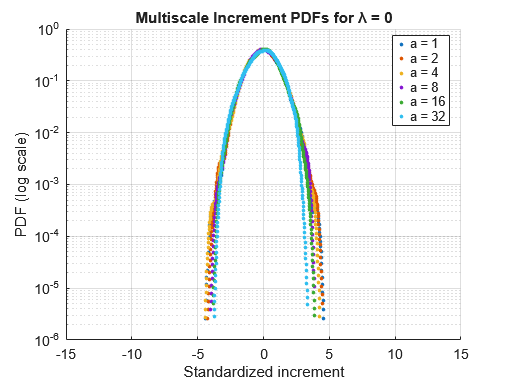

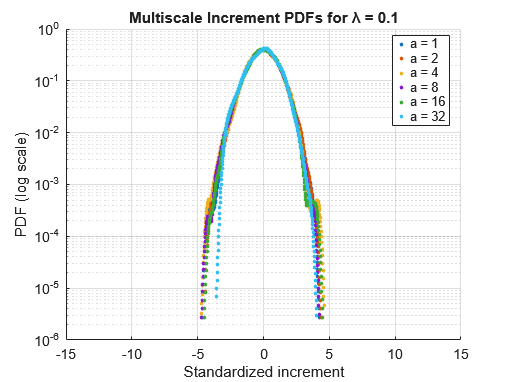

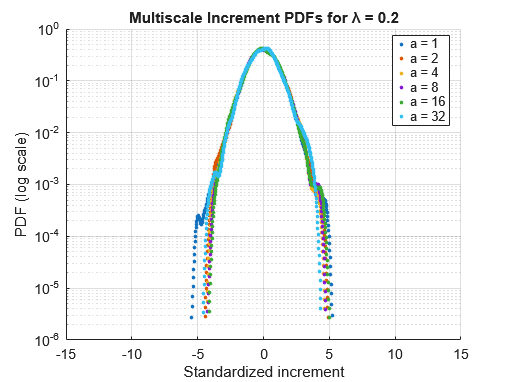

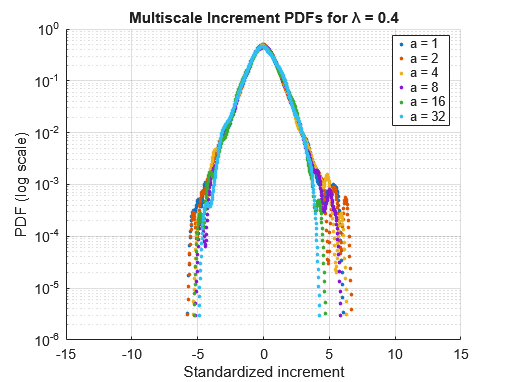

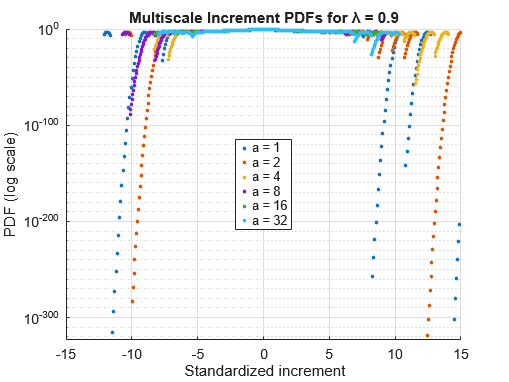


%% ---------------------------------------------------------
% MULTISCALE PDF COMPARISON (one figure per lambda)
% ---------------------------------------------------------

scales = [1, 2, 4, 8, 16, 32];   % coarse-graining scales
colorsS = lines(numel(scales)); % colors for scales

for hi = 1:numH
    figure; hold on;

    for si = 1:numel(scales)
        a = scales(si);

        % Use the largest N for best statistics
        x = mrw{hi, end};   % take N = max(Nvals)

        % Coarse-grained increments: X(t+a) - X(t)
        dXa = x(1+a:end) - x(1:end-a);

        % Standardize
        dXa = (dXa - mean(dXa)) / std(dXa);

        % Kernel density estimate for smooth PDF
        [pdf_vals, x_vals] = ksdensity(dXa, 'NumPoints', 400);

        % Plot as dots
        plot(x_vals, pdf_vals, '.', ...
            'Color', colorsS(si,:), ...
            'MarkerSize', 8, ...
            'DisplayName', "a = " + string(a));
    end

    set(gca,'YScale','log')
    xlabel("Standardized increment")
    xlim([-15 15])
    ylabel("PDF (log scale)")
    title("Multiscale Increment PDFs for λ = " + string(lambda(hi)))
    legend("Location","best")
    grid on
end

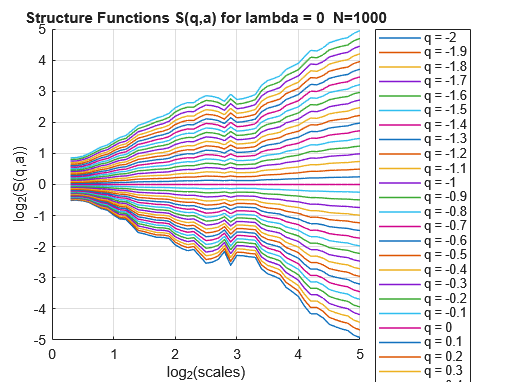

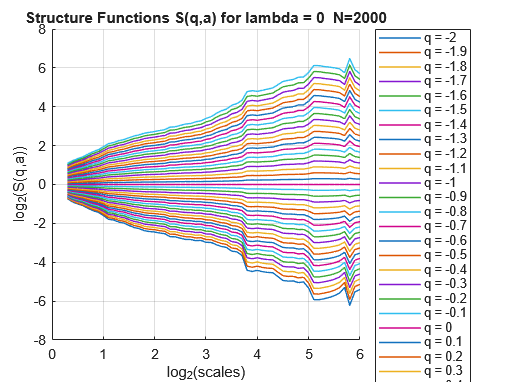

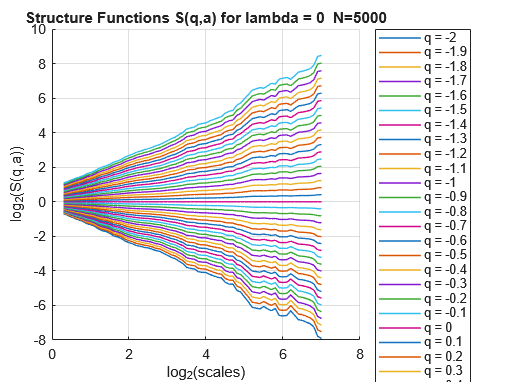

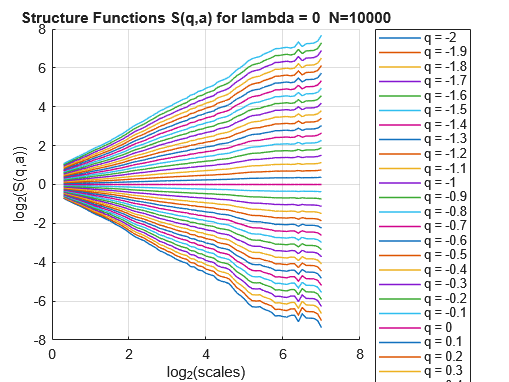

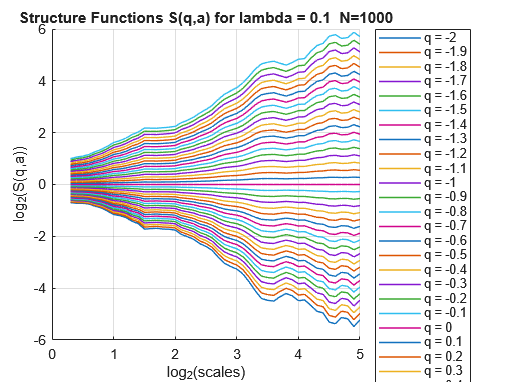

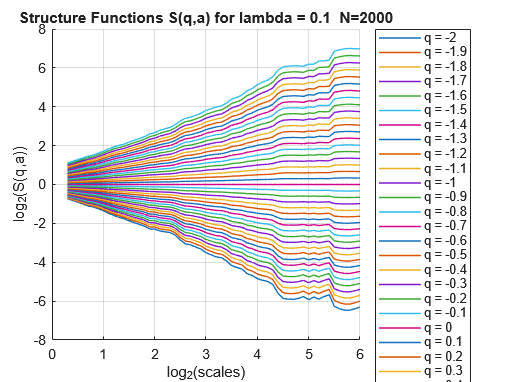

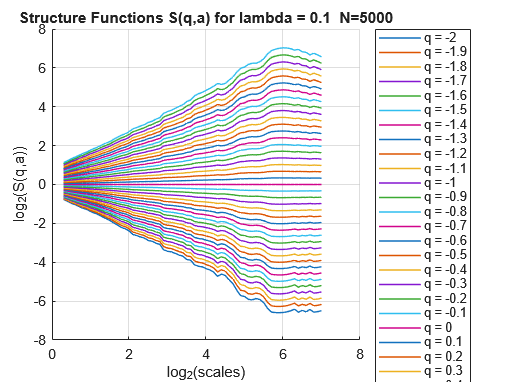

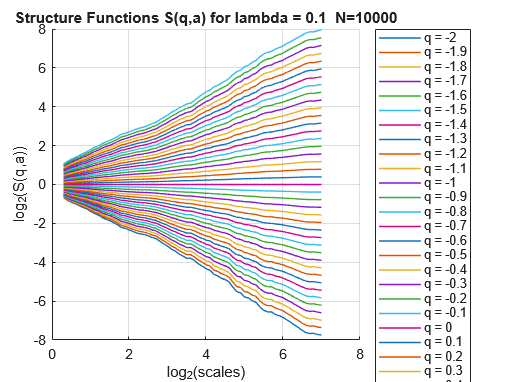



%% ---------------------------------------------------------
% 2. STRUCTURE FUNCTIONS S(q,a) (LOG–LOG) FOR EACH (H, N)
% Reads structfunc{hi,ni}.Tq and .logscales
% ---------------------------------------------------------

q_axis = -2:0.1:2;   % q values for WTMM structure functions

for hi = 1:numH
    for ni = 1:numN
        S    = structfunc{hi,ni}.Tq(:, 1:41);      % structure functions for q=-5:5
        loga = structfunc{hi,ni}.logscales;        % log2(a)

        figure; hold on;
        plot(loga, S, 'LineWidth', 1.0)
        

        % Legend labels: "a = scale_value"
        legendStrings = "q = " + string(round(q_axis, 3));
        legend(legendStrings, "Location", "bestoutside")

        xlabel("log_2(scales)")
        ylabel("log_2(S(q,a))")
        title("Structure Functions S(q,a) for lambda = " + string(lambda(hi))+ ...
              "  N="+string(Nvals(ni)))
        grid on
    end
end

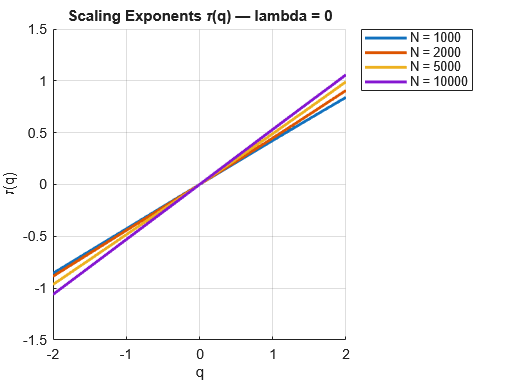

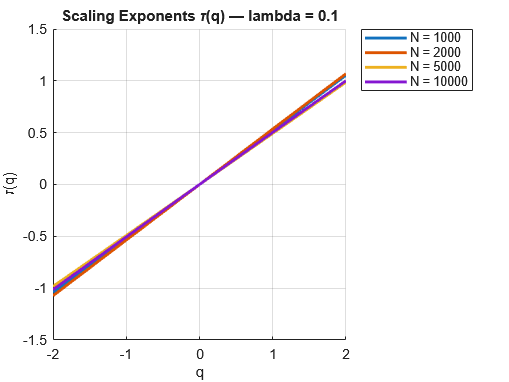

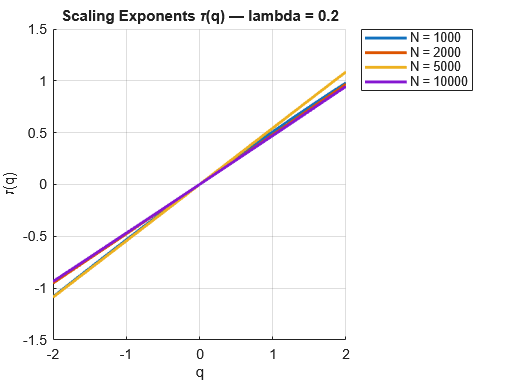

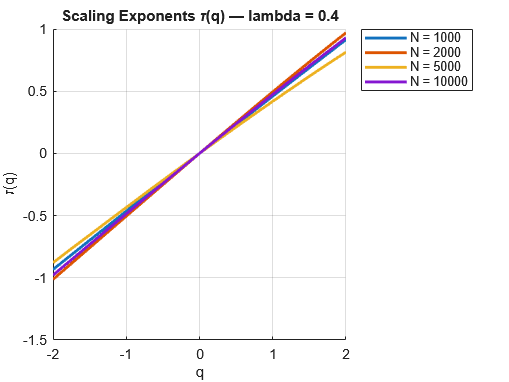

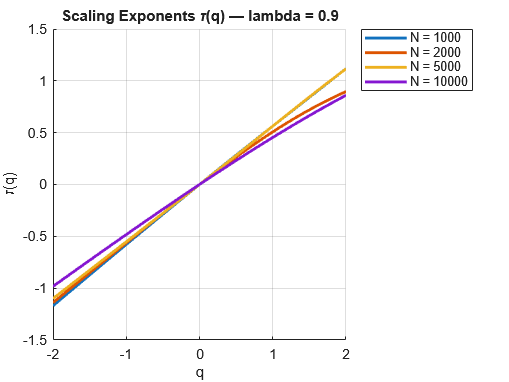




%% ---------------------------------------------------------
% 6. PLOT τ(q) FOR ALL Nvals (separate figure)
% ---------------------------------------------------------
q_axis = linspace(-2, 2, 41);

for hi = 1:numH
    figure; hold on;

    for ni = 1:numN
        tau = tauq{hi,ni};

        plot(q_axis, tau, 'LineWidth', 2, ...
            'Color', colorsN(ni,:), ...
            'DisplayName', "N = " + string(Nvals(ni)));
    end

    xlabel("q");
    ylabel("\tau(q)");
    title("Scaling Exponents \tau(q) — lambda = " + string(lambda(hi)));
    legend("Location","bestoutside");
    grid on;
end

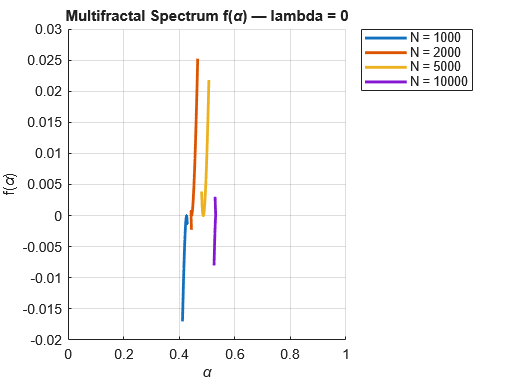

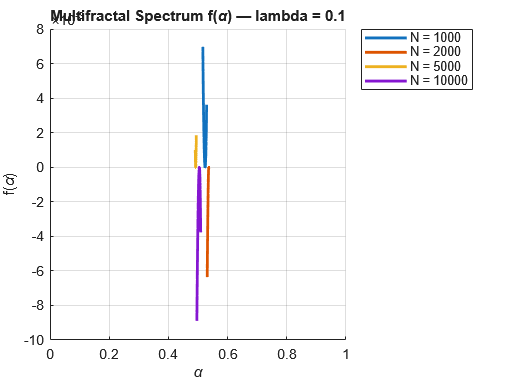

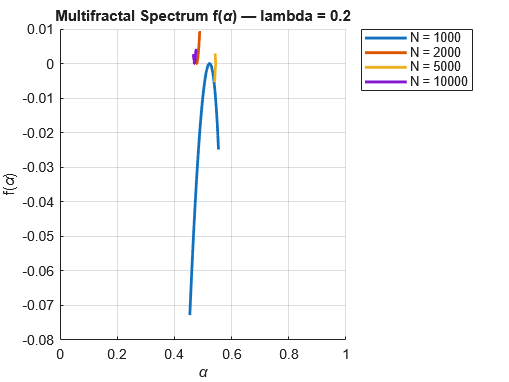

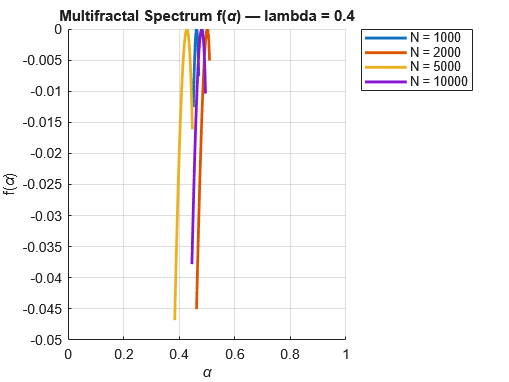

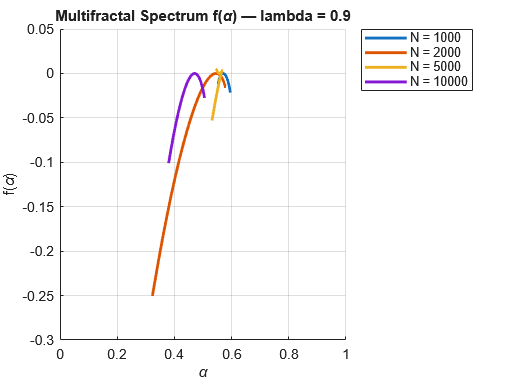



%% ---------------------------------------------------------
% 7. PLOT f(α) FOR ALL Nvals (separate figure)
% ---------------------------------------------------------
for hi = 1:numH
    figure; hold on;

    for ni = 1:numN
        a_q = alpha_q{hi,ni};
        f_a = f_alpha{hi,ni};

        plot(a_q, f_a, 'LineWidth', 2, ...
            'Color', colorsN(ni,:), ...
            'DisplayName', "N = " + string(Nvals(ni)));
    end

    xlabel("\alpha");
    ylabel("f(\alpha)");
    xlim([0 1])
    title("Multifractal Spectrum f(\alpha) — lambda = " + string(lambda(hi)));
    legend("Location","bestoutside");
    grid on;
end